% AE6511 Hw5 Problem 2 MATLAB code
% Tomoki Koike
clear all; close all; clc;  % housekeeping commands
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');

%% (a)
syms t c c_1 c_2 c_3 e
assume(c, 'real');
assume(c_1, 'real');
assume(c_2, 'real');
assume(c_3, 'real');
x_1(t) = -c_1/2 * exp(t) - c_2 * exp(-t) - c*t + c_3;
x_2(t) = -c_1/2 * exp(t) + c_2*exp(-t) - c;
% x_1(t) = -c_1/2 * e^(t) - c_2 * e^(-t) - c*t + c_3;
% x_2(t) = -c_1/2 * e^(t) + c_2*e^(-t) - c;

% solve for unknowns with the boundary conditions
eqns = [x_1(0)==0, x_2(0)==0, x_1(3)==1, x_2(3)==2];
sol = solve(eqns, [c, c_1, c_2, c_3]);
sol.c
sol.c_1
sol.c_2
sol.c_3

% Find the minimum performance index
l1 = sol.c;
l2(t) = sol.c_1 * exp(t) + sol.c;
x_1n(t) = subs(x_1, [c, c_1, c_2, c_3], [sol.c sol.c_1 sol.c_2 sol.c_3]);
x_2n(t) = subs(x_2, [c, c_1, c_2], [sol.c sol.c_1 sol.c_2]);
u = -l2;
H(t) = 0.5 * u^2 + l1 * x_2n + l2 * (-x_2n + u);
J_min = 1/2 * int(u^2, 0, 3)

% Plotting the result
% t
tspan = linspace(0, 3, 1000);
fig = figure("Renderer","painters","Position",[60 60 900 800]);
    % x1 vs t
    subplot(2,2,1)
    plot(tspan, x_1n(tspan))
    title('$x_1$ Over Time')
    xlabel('$t$')
    ylabel('$x_1$')
    grid on; grid minor; box on;
    % x2 vs t
    subplot(2,2,2)
    plot(tspan, x_2n(tspan))
    title('$x_2$ Over Time')
    xlabel('$t$')
    ylabel('$x_2$')
    grid on; grid minor; box on;
    % x_1 - x_2 
    subplot(2,2,3)
    plot(x_1n(tspan), x_2n(tspan))
    title('$x_1$ vs $x_2$')
    xlabel('$x_1$')
    ylabel('$x_2$')
    grid on; grid minor; box on;
    % Hamiltonian 
    subplot(2,2,4)
    plot(tspan, H(tspan))
    title('Hamiltonian')
    xlabel('$t$')
    ylabel('$H$')
    grid on; grid minor; box on;
% saveas(fig, 'p2a.png')

%% (b)
syms t c_1 c_2 c_3 e
assume(c_1, 'real');
assume(c_2, 'real');
assume(c_3, 'real');
x_1(t) = -c_1/2 * exp(t) - c_2 * exp(-t) + c_1*exp(3)*t + c_3;
x_2(t) = -c_1/2 * exp(t) + c_2*exp(-t) + c_1*exp(3);
% x_1(t) = -c_1/2 * e^(t) - c_2 * e^(-t) + c_1*e^3*t + c_3;
% x_2(t) = -c_1/2 * e^(t) + c_2*e^(-t) + c_1*e^3;

% solve for unknowns with the boundary conditions
eqns = [x_1(0)==0, x_2(0)==0, x_1(3)==1];
sol = solve(eqns, [c_1, c_2, c_3]);
sol.c_1
sol.c_2
sol.c_3

% Find the minimum performance index
l1 = -sol.c_1 * exp(3);
l2(t) = sol.c_1 * exp(t) + l1;
x_1n(t) = subs(x_1, [c_1, c_2, c_3], [sol.c_1 sol.c_2 sol.c_3]);
x_2n(t) = subs(x_2, [c_1, c_2], [sol.c_1 sol.c_2]);
u = -l2;
H(t) = 0.5 * u^2 + l1 * x_2n + l2 * (-x_2n + u);
J_min = 1/2 * int(u^2, 0, 3)

% Plotting the result
% t
tspan = linspace(0, 3, 1000);
fig = figure("Renderer","painters","Position",[60 60 900 800]);
    % x1 vs t
    subplot(2,2,1)
    plot(tspan, x_1n(tspan))
    title('$x_1$ Over Time')
    xlabel('$t$')
    ylabel('$x_1$')
    grid on; grid minor; box on;
    % x2 vs t
    subplot(2,2,2)
    plot(tspan, x_2n(tspan))
    title('$x_2$ Over Time')
    xlabel('$t$')
    ylabel('$x_2$')
    grid on; grid minor; box on;
    % x_1 - x_2 
    subplot(2,2,3)
    plot(x_1n(tspan), x_2n(tspan))
    title('$x_1$ vs $x_2$')
    xlabel('$x_1$')
    ylabel('$x_2$')
    grid on; grid minor; box on;
    % Hamiltonian 
    subplot(2,2,4)
    plot(tspan, H(tspan))
    title('Hamiltonian')
    xlabel('$t$')
    ylabel('$H$')
    grid on; grid minor; box on;
saveas(fig, 'p2b.png')

%% (c)
syms t c c_1 c_2 c_3 e
assume(c, 'real');
assume(c_1, 'real');
assume(c_2, 'real');
assume(c_3, 'real');
x_1(t) = -c_1/2 * exp(t) - c_2 * exp(-t) - c*t + c_3;
x_2(t) = -c_1/2 * exp(t) + c_2*exp(-t) - c;
lambda1 = c;
lambda2(t) = c_1 * exp(t) + c;
% x_1(t) = -c_1/2 * e^(t) - c_2 * e^(-t) - c*t + c_3;
% x_2(t) = -c_1/2 * e^(t) + c_2*e^(-t) - c;
% lambda1 = c;
% lambda2(t) = c_1 * e^(t) + c;

% solve for unknowns with the boundary conditions
TC1 = lambda1 == 2 * (x_1(3) - 1);
TC2 = lambda2(3) == 2 * (x_2(3) - 2);
eqns = [x_1(0)==0, x_2(0)==0, TC1, TC2];
sol = solve(eqns, [c, c_1, c_2, c_3]);
sol.c

$$ans = -0.0507$$

sol.c_1

$$ans = -0.0960$$

sol.c_2

$$ans = -0.0987$$

sol.c_3

$$ans = -0.1467$$

% Find the minimum performance index
l1 = sol.c;
l2(t) = sol.c_1 * exp(t) + sol.c;
x_1n(t) = subs(x_1, [c, c_1, c_2, c_3], [sol.c sol.c_1 sol.c_2 sol.c_3]);
x_2n(t) = subs(x_2, [c, c_1, c_2], [sol.c sol.c_1 sol.c_2]);
u = -l2;
H(t) = 0.5 * u^2 + l1 * x_2n + l2 * (-x_2n + u);
Phi = (x_1n - 1)^2 + (x_2n - 2)^2;
J_min = simplify(Phi(3) + 1/2 * int(u^2, 0, 3))

$$J\_min = 2.0049$$

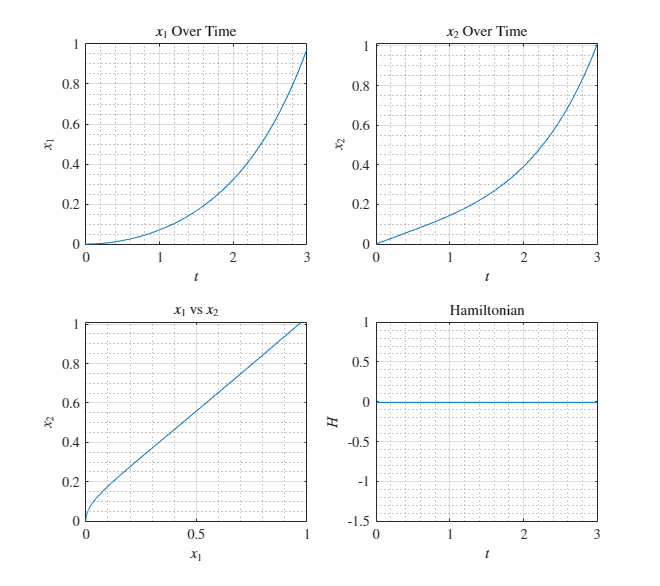

% Plotting the result
% t
tspan = linspace(0, 3, 1000);
fig = figure("Renderer","painters","Position",[60 60 900 800]);
    % x1 vs t
    subplot(2,2,1)
    plot(tspan, x_1n(tspan))
    title('$x_1$ Over Time')
    xlabel('$t$')
    ylabel('$x_1$')
    grid on; grid minor; box on;
    % x2 vs t
    subplot(2,2,2)
    plot(tspan, x_2n(tspan))
    title('$x_2$ Over Time')
    xlabel('$t$')
    ylabel('$x_2$')
    grid on; grid minor; box on;
    % x_1 - x_2 
    subplot(2,2,3)
    plot(x_1n(tspan), x_2n(tspan))
    title('$x_1$ vs $x_2$')
    xlabel('$x_1$')
    ylabel('$x_2$')
    grid on; grid minor; box on;
    % Hamiltonian 
    subplot(2,2,4)
    plot(tspan, H(tspan))
    title('Hamiltonian')
    xlabel('$t$')
    ylabel('$H$')
    grid on; grid minor; box on;
saveas(fig, 'p2c.png')

%% (d)
syms t c c_1 c_2 c_3 e
assume(c, 'real');
assume(c_1, 'real');
assume(c_2, 'real');
assume(c_3, 'real');
x_1(t) = -c_1/2 * exp(t) - c_2 * exp(-t) - c*t + c_3;
x_2(t) = -c_1/2 * exp(t) + c_2*exp(-t) - c;
lambda1 = c;
lambda2(t) = c_1 * exp(t) + c;

% x_1(t) = -c_1/2 * e^(t) - c_2 * e^(-t) - c*t + c_3;
% x_2(t) = -c_1/2 * e^(t) + c_2*e^(-t) - c;
% lambda1 = c;
% lambda2(t) = c_1 * e^(t) + c;

% solve for unknowns with the boundary conditions
TC1 = lambda2(3) == 5/2 * lambda1;
TC2 = 2*x_1(3) + 5*x_2(3) == 20;
eqns = [x_1(0)==0, x_2(0)==0, TC1, TC2];
sol = solve(eqns, [c, c_1, c_2, c_3]);
sol.c

$$ans = -1.4341$$

sol.c_1

$$ans = -0.1071$$

sol.c_2

$$ans = -1.4877$$

sol.c_3

$$ans = -1.5412$$

% Find the minimum performance index
l1 = sol.c;
l2(t) = sol.c_1 * exp(t) + sol.c;
x_1n(t) = subs(x_1, [c, c_1, c_2, c_3], [sol.c sol.c_1 sol.c_2 sol.c_3]);
x_2n(t) = subs(x_2, [c, c_1, c_2], [sol.c sol.c_1 sol.c_2]);
u = -l2;
H(t) = 0.5 * u^2 + l1 * x_2n + l2 * (-x_2n + u);
Phi = (x_1n - 1)^2 + (x_2n - 2)^2;
J_min = simplify(Phi(3) + 1/2 * int(u^2, 0, 3))

$$J\_min = 15.8334$$

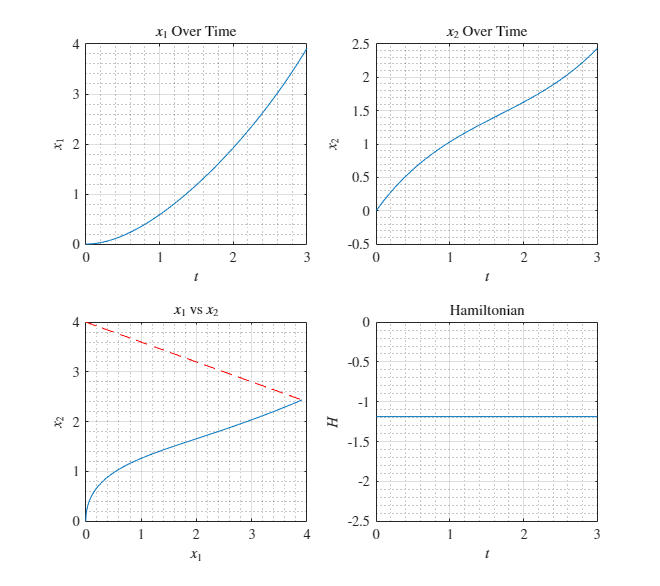

% Plotting the result
% t
tspan = linspace(0, 3, 1000);
fig = figure("Renderer","painters","Position",[60 60 900 800]);
    % x1 vs t
    subplot(2,2,1)
    plot(tspan, x_1n(tspan))
    title('$x_1$ Over Time')
    xlabel('$t$')
    ylabel('$x_1$')
    grid on; grid minor; box on;
    % x2 vs t
    subplot(2,2,2)
    plot(tspan, x_2n(tspan))
    title('$x_2$ Over Time')
    xlabel('$t$')
    ylabel('$x_2$')
    grid on; grid minor; box on;
    % x_1 - x_2 
    subplot(2,2,3)
    plot(x_1n(tspan), x_2n(tspan))
    hold on;
    plot(x_1n(tspan), -2/5 * x_1n(tspan) + 4, '--r')
    title('$x_1$ vs $x_2$')
    xlabel('$x_1$')
    ylabel('$x_2$')
    grid on; grid minor; box on; hold off;
    % Hamiltonian 
    subplot(2,2,4)
    plot(tspan, H(tspan))
    title('Hamiltonian')
    xlabel('$t$')
    ylabel('$H$')
    grid on; grid minor; box on;
saveas(fig, 'p2d.png')

%% (e)
syms t c c_1 c_2 c_3 e t_f
assume(c, 'real');
assume(c_1, 'real');
assume(c_2, 'real');
assume(c_3, 'real');
x_1(t) = -c_1/2 * exp(t) - c_2 * exp(-t) - c*t + c_3;
x_2(t) = -c_1/2 * exp(t) + c_2*exp(-t) - c;
lambda1 = c;
lambda2(t) = c_1 * exp(t) + c;
U(t) = -lambda2;
HH(t) = 0.5*U^2 + lambda1 * x_2 + lambda2 * (-x_2 + U);

% solve for unknowns with the boundary conditions
TC1 = lambda2(t_f) == 5/2 * lambda1;
TC2 = HH(t_f) == t_f * lambda1 / 2;
TC3 = 2*x_1(t_f) + 5*x_2(t_f) == 20 + t_f^2 / 2;
eqns = [x_1(0)==0, x_2(0)==0, TC1, TC2, TC3];
sol = vpasolve(eqns, [c, c_1, c_2, c_3 t_f]);
sol.c

$$ans = -1.8359$$

sol.c_1

$$ans = -0.2547$$

sol.c_2

$$ans = -1.9633$$

sol.c_3

$$ans = -2.0906$$

sol.t_f

$$ans = 2.3807$$

% Find the minimum performance index
l1 = sol.c;
l2(t) = sol.c_1 * exp(t) + sol.c;
x_1n(t) = subs(x_1, [c, c_1, c_2, c_3], [sol.c sol.c_1 sol.c_2 sol.c_3]);
x_2n(t) = subs(x_2, [c, c_1, c_2], [sol.c sol.c_1 sol.c_2]);
u = -l2;
H(t) = 0.5 * u^2 + l1 * x_2n + l2 * (-x_2n + u);
Phi = (x_1n - 1)^2 + (x_2n - 2)^2;
J_min = simplify(1/2 * int(u^2, 0, sol.t_f))

$$J\_min = 10.4803$$

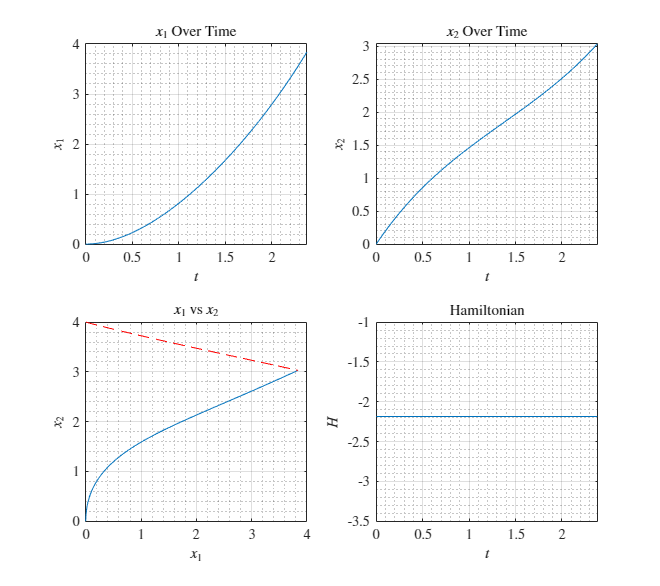

% Plotting the result
% t
tspan = linspace(0, sol.t_f, 1000);
fig = figure("Renderer","painters","Position",[60 60 900 800]);
    % x1 vs t
    subplot(2,2,1)
    plot(tspan, x_1n(tspan))
    title('$x_1$ Over Time')
    xlabel('$t$')
    ylabel('$x_1$')
    grid on; grid minor; box on;
    % x2 vs t
    subplot(2,2,2)
    plot(tspan, x_2n(tspan))
    title('$x_2$ Over Time')
    xlabel('$t$')
    ylabel('$x_2$')
    grid on; grid minor; box on;
    % x_1 - x_2 
    subplot(2,2,3)
    plot(x_1n(tspan), x_2n(tspan))
    hold on;
    plot(x_1n(tspan), -2/5 * x_1n(tspan) + 4 + tspan.^2 / 10, '--r')
    title('$x_1$ vs $x_2$')
    xlabel('$x_1$')
    ylabel('$x_2$')
    grid on; grid minor; box on; hold off;
    % Hamiltonian 
    subplot(2,2,4)
    plot(tspan, H(tspan))
    title('Hamiltonian')
    xlabel('$t$')
    ylabel('$H$')
    grid on; grid minor; box on;
saveas(fig, 'p2e.png')